% Reading input image : input_image
fprintf("PLEASE SELECT AN IMAGE\n")

PLEASE SELECT AN IMAGE


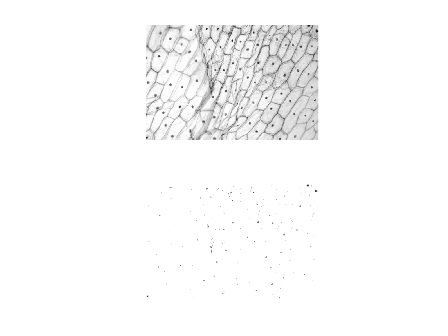

i=uigetfile('*.*');
input_image = imread(i);
% MATLAB Code | Geometric Mean Filterinput_image = imread(i);
input_image=rgb2gray(input_image);
% Saving the size of the input_image in pixels-
% M : no of rows (height of the image)
% N : no of columns (width of the image)
[M, N] = size(input_image);

% Defining the window size for median filter
ws = 3;

% Getting the padded image for the edge pixels
padded_image = padarray(input_image, [(ws-1)/2 (ws-1)/2], 'replicate');

% Initializing the output image
output_image = zeros(size(input_image));

% Performing the midpoint filtering
for i = 1:M
    for j = 1:N
        % Extracting the sub-image
        sub_image = padded_image(i:i+ws-1, j:j+ws-1);
        
        % Calculating the midpoint
        mid_point = (max(sub_image(:)) + min(sub_image(:))) / 2;
        
        % Updating the pixel value in the output image
        output_image(i,j) = mid_point;
    end
end

% Displaying Input Image and Output Image
subplot(2, 1, 1), imshow(input_image),
subplot(2, 1, 2), imshow(output_image,[]);